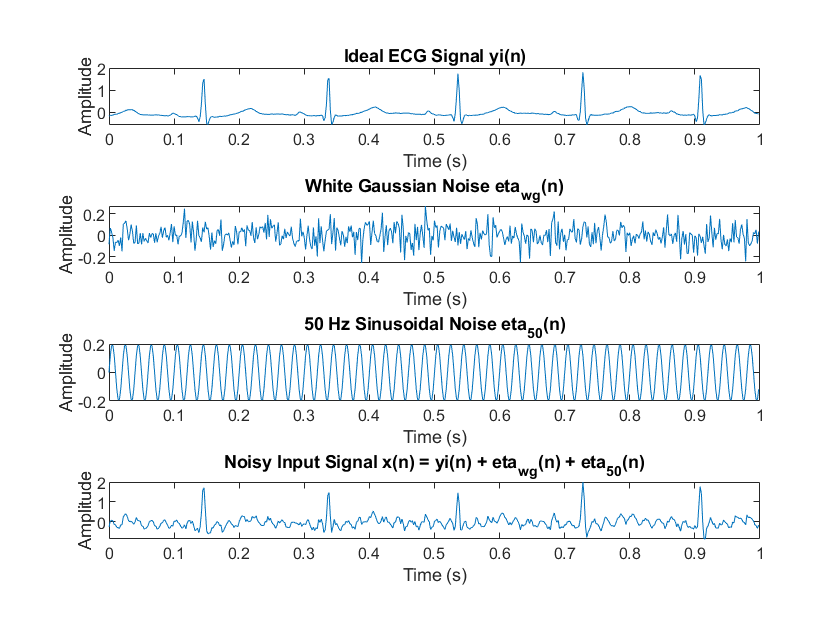

clear; clc;

% Data construction

load('idealECG.mat');
y_ideal = idealECG;

N = length(y_ideal); % Length of the signal
fs = 500;   % Sampling frequency (Hz)
t = (0 : N-1) / fs; % Calculating time points

% Create the 50 Hz sinusoidal noise component
f_n = 50;   % Noise frequency
eta_50 = 0.2 * sin(2 * pi * f_n * t);

% Add white Gaussian noise to the ideal signal
yi_noisy = awgn(y_ideal, 10, 'measured');    % Adding white Gaussian noise of 10dB SNR
eta_wg = yi_noisy - y_ideal; %white gaussian noise component
% Combine the sinusoidal noise with white gaussian noise
noise = eta_wg + eta_50;  % Total noisy signal
x = y_ideal + noise;
x_in = x - mean(x); % Input Signal (offset corrected)

figure(1);
subplot(4,1,1);
plot(t(1:500), y_ideal(1:500));
title('Ideal ECG Signal yi(n)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,2);
plot(t(1:500), eta_wg(1:500));
title('White Gaussian Noise eta_{wg}(n)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,3);
plot(t(1:500), eta_50(1:500));
title('50 Hz Sinusoidal Noise eta_{50}(n)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,4);
plot(t(1:500), x(1:500));
title('Noisy Input Signal x(n) = yi(n) + eta_{wg}(n) + eta_{50}(n)');
xlabel('Time (s)');
ylabel('Amplitude');

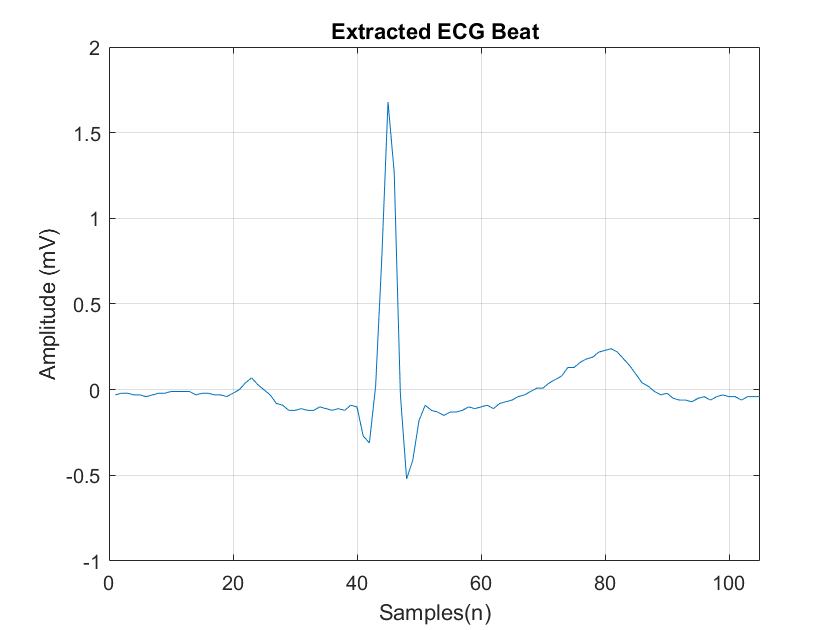

%1.1 Part 1
s1 = 500;          % start index
e1 = 604;          % end index
y_seg = y_ideal(s1 : e1);
y_seg = y_seg- mean(y_seg); 

% Plot extracted beat
figure;
plot(y_seg); 
title('Extracted ECG Beat');
xlabel('Samples(n)'); ylabel('Amplitude (mV)');
xlim([0 105])
grid on;

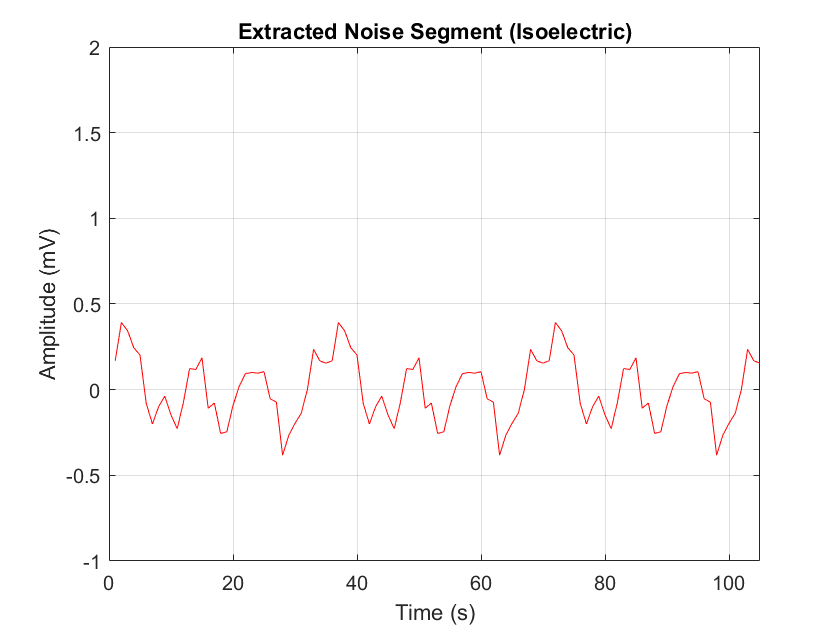

n_start = 581;  
n_end   = 615;   
n_seg1 = x_in(n_start:n_end);
n_seg1 = repmat(n_seg1, 1, 3); 
n_seg1 = n_seg1 - mean(n_seg1); 

% Plot extracted noise segment
figure;
plot(n_seg1, 'r');
ylim([-1 2])
xlim([0 105]);
title('Extracted Noise Segment (Isoelectric)');
xlabel('Time (s)'); ylabel('Amplitude (mV)');
grid on;

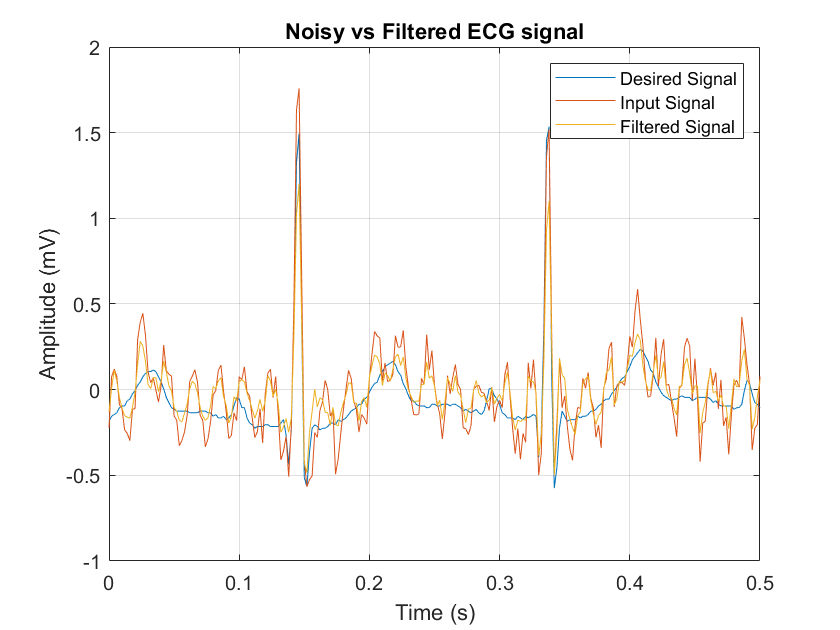


M = 20; %Filter order

% Autocorrelation of desired
R_YY = xcorr(y_seg, M-1, 'unbiased');
R_YY_M = toeplitz(R_YY(M:end));

% Autocorrelation of noise
R_NN = xcorr(n_seg1, M-1, 'unbiased');
R_NN_M = toeplitz(R_NN(M:end));

% Cross-correlation vector (between y and itself at zero lag)
R_Yy = R_YY(M:end);

% Wiener solution
w = (R_YY_M + R_NN_M)\ R_Yy(:);
y_hat = filter(w, 1, x_in); % Apply filter

figure();
plot(t, y_ideal, t, x_in, t, y_hat);
title('Noisy vs Filtered ECG signal');
xlim([0 0.5])
xlabel('Time (s)');
ylabel('Amplitude (mV)');
legend('Desired Signal', 'Input Signal', 'Filtered Signal');
grid on;

%b) Find the optimum filter order and its coefficients. Plot the magnitude response
% Initialize the matrix to store MSE values

M_range = 1:35;                
MSE_matrix = zeros(size(M_range));

for k = 1:length(M_range)
    M = M_range(k);

    % Autocorr matrices
    R_YY = xcorr(y_seg, M-1, 'unbiased');
    R_YY_M = toeplitz(R_YY(M:end));

    R_NN = xcorr(n_seg1, M-1, 'unbiased');
    R_NN_M = toeplitz(R_NN(M:end));

    % Cross-corr vector 
    R_Yy = R_YY(M:end);

    % Wiener solution
    w_k = (R_YY_M + R_NN_M) \ R_Yy';

    % Filter only the beat segment
    x_seg = x_in(s1:e1);
    y_hat_k = filter(w_k, 1, x_seg);

    % MSE
    MSE_matrix(k) = mean((y_seg - y_hat_k).^2);
end

% Find optimum
[minMSE, idx] = min(MSE_matrix);
M_opt = M_range(idx);

fprintf('Optimum filter order = %d, Minimum MSE = %.6f\n', M_opt, minMSE);

Optimum filter order = 21, Minimum MSE = 0.014673


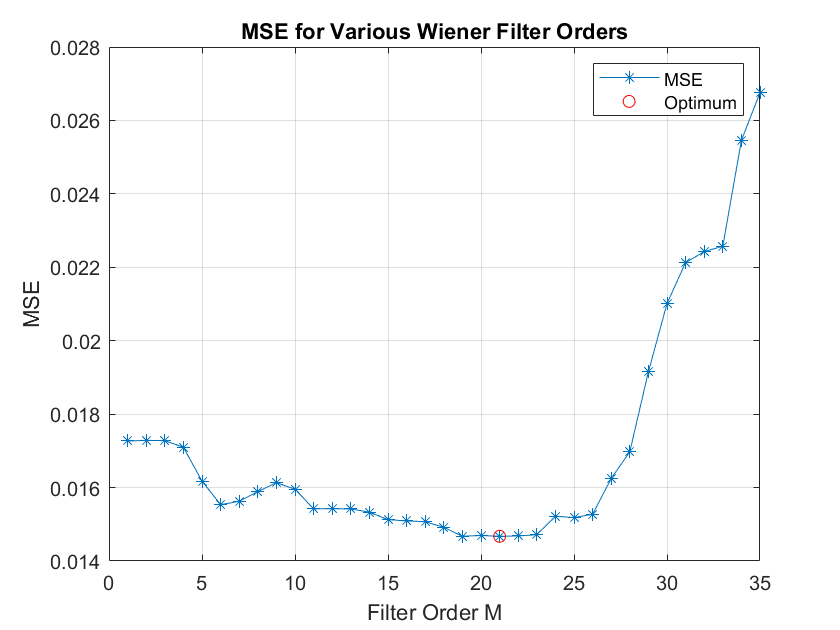


% Plot MSE vs order
figure;
plot(M_range, MSE_matrix, '-*'); grid on;
xlabel('Filter Order M'); ylabel('MSE');

title('MSE for Various Wiener Filter Orders');
hold on; plot(M_opt, minMSE, 'ro'); legend('MSE','Optimum');

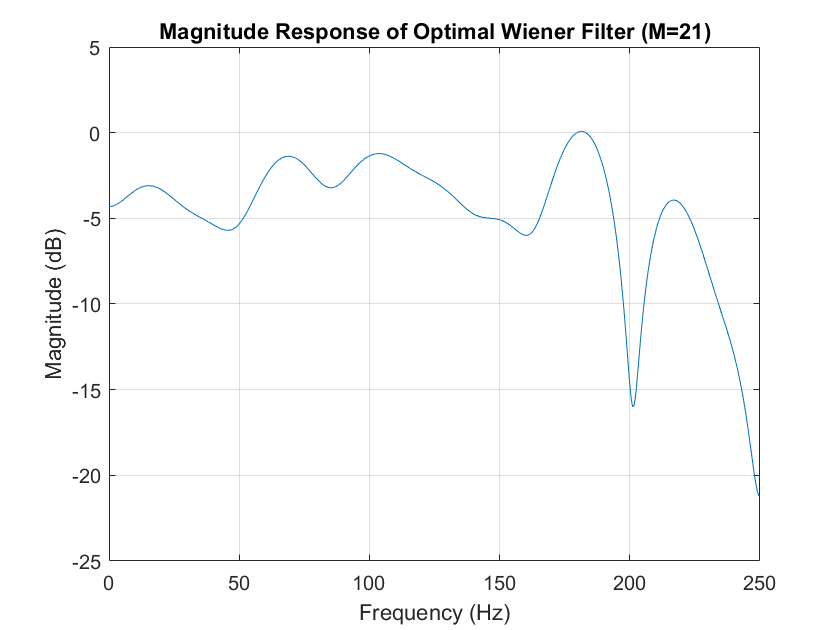

% Recompute optimal filter coefficients
Ryy = xcorr(y_seg, M_opt-1, 'unbiased');
RyyM = toeplitz(Ryy(M_opt:end));
Rnn = xcorr(n_seg1, M_opt-1, 'unbiased');
RnnM = toeplitz(Rnn(M_opt:end));
Ryy_cross = Ryy(M_opt:end);
w_optimal = (RyyM + RnnM) \ Ryy_cross(:);



% Magnitude response
[H, f] = freqz(w_optimal, 1, 1024, fs);
figure;
plot(f, 20*log10(abs(H)+eps));
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
title(sprintf('Magnitude Response of Optimal Wiener Filter (M=%d)', M_opt));
grid on;

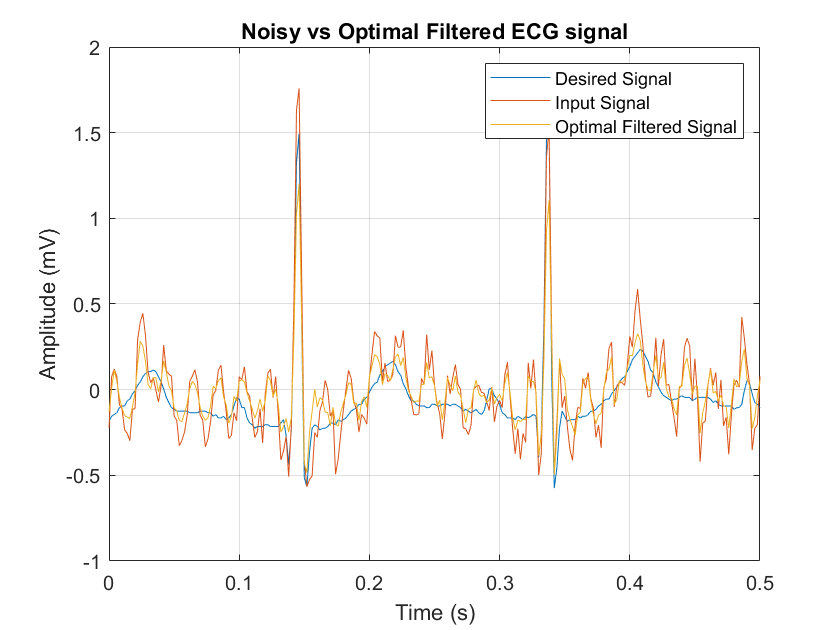

% (c) Obtain the filtered signal using the filter obtained above

y_optimal = filter(w_optimal, 1, x_in); % Apply optimal filter

figure();
plot(t, y_ideal, t, x_in, t, y_optimal);
title('Noisy vs Optimal Filtered ECG signal');
xlim([0 0.5])
xlabel('Time (s)');
ylabel('Amplitude (mV)');
legend('Desired Signal','Input Signal', 'Optimal Filtered Signal');
grid on;

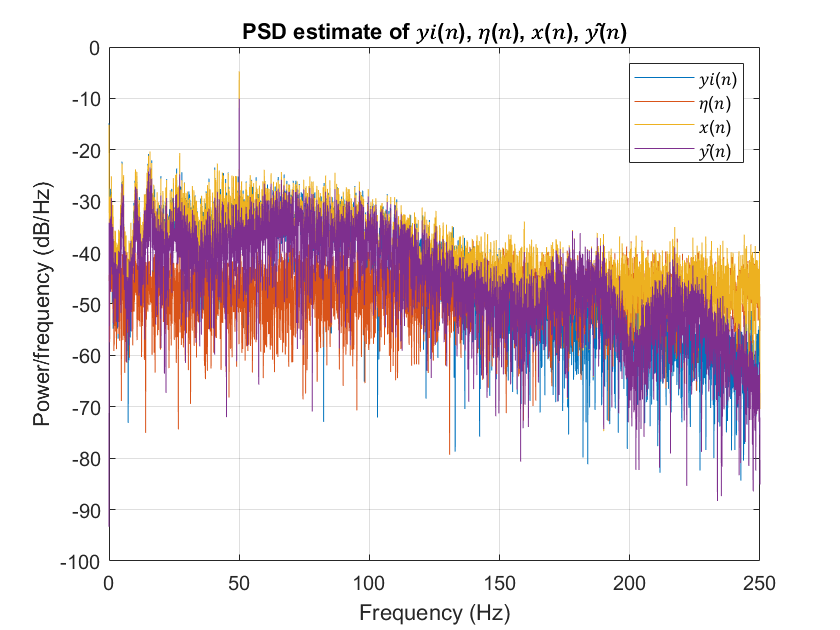



% (d) Plot the spectra of 𝑦𝑖(𝑛), 𝜂(𝑛), 𝑥(𝑛), 𝑦̂(𝑛) on the same plot

window = rectwin(N);


[P1,f1] = periodogram(y_ideal, window, N, fs);   % PSD estimate of a of 𝑦𝑖(𝑛)
[P2,f2] = periodogram(noise, window, N, fs);   % PSD estimate of 𝜂(𝑛)
[P3,f3] = periodogram(x, window, N, fs);    % PSD estimate of 𝑥(𝑛)
[P4,f4] = periodogram(y_optimal, window, N, fs);    % PSD estimate of 𝑦̂(𝑛)

figure();
plot(f1, 10*log10(P1), f2, 10*log10(P2), f3, 10*log10(P3), f4, 10*log10(P4));   % Plotting the PSDs
title('PSD estimate of 𝑦𝑖(𝑛), 𝜂(𝑛), 𝑥(𝑛), 𝑦̂(𝑛)');
xlabel('Frequency (Hz)');
ylabel('Power/frequency (dB/Hz)');
legend('𝑦𝑖(𝑛)', '𝜂(𝑛)', '𝑥(𝑛)', '𝑦̂(𝑛)');
grid on;

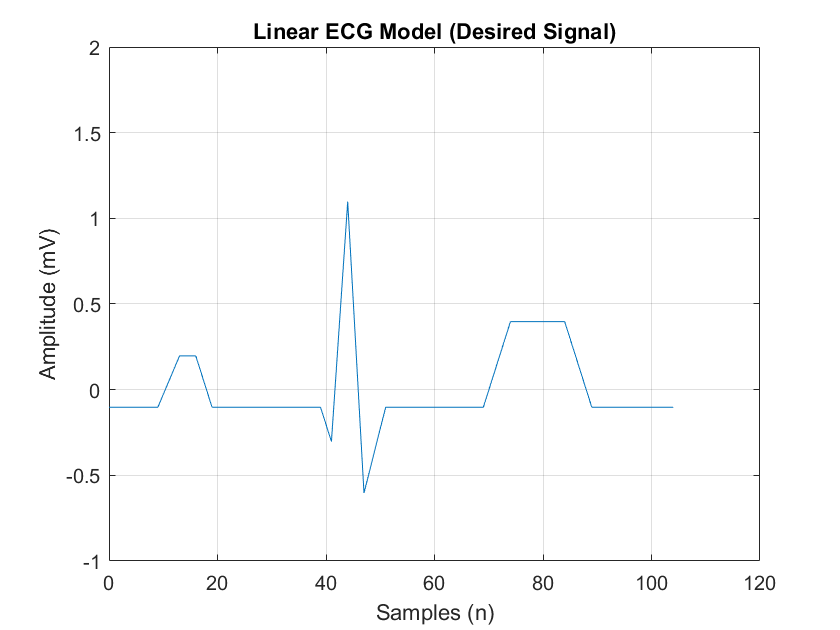

%Part 2: Linear ECG Model


fs = 500;           % sampling frequency (Hz)
N = 105;            % samples per beat
t = (0:N-1);

% Initialize model signal with zeros (baseline)
model = zeros(1,N);


p_start = 10; p_up = 14; p_flat_end = 17; p_end = 20;
q_start = 40; q_peak = 42; r_peak = 45; s_peak = 48; qrs_end = 52;
t_start = 70; t_up = 75; t_flat_end = 85; t_end = 90;

% linear model beat 
model(p_start:p_up)       = linspace(0,0.3,p_up-p_start+1);
model(p_up:p_flat_end)    = 0.3;
model(p_flat_end:p_end)   = linspace(0.3,0,p_end-p_flat_end+1);

model(q_start:q_peak)     = linspace(0,-0.2,q_peak-q_start+1);
model(q_peak:r_peak)      = linspace(-0.2,1.2,r_peak-q_peak+1);
model(r_peak:s_peak)      = linspace(1.2,-0.5,s_peak-r_peak+1);
model(s_peak:qrs_end)     = linspace(-0.5,0,qrs_end-s_peak+1);

model(t_start:t_up)       = linspace(0,0.5,t_up-t_start+1);
model(t_up:t_flat_end)    = 0.5;
model(t_flat_end:t_end)   = linspace(0.5,0,t_end-t_flat_end+1);

y_seg_2 = model- mean(model);   % desired signal (zero-mean)
figure; plot(t,y_seg_2);
xlabel('Samples (n)'); ylabel('Amplitude (mV)');
title('Linear ECG Model (Desired Signal)');
grid on; ylim([-1 2]);

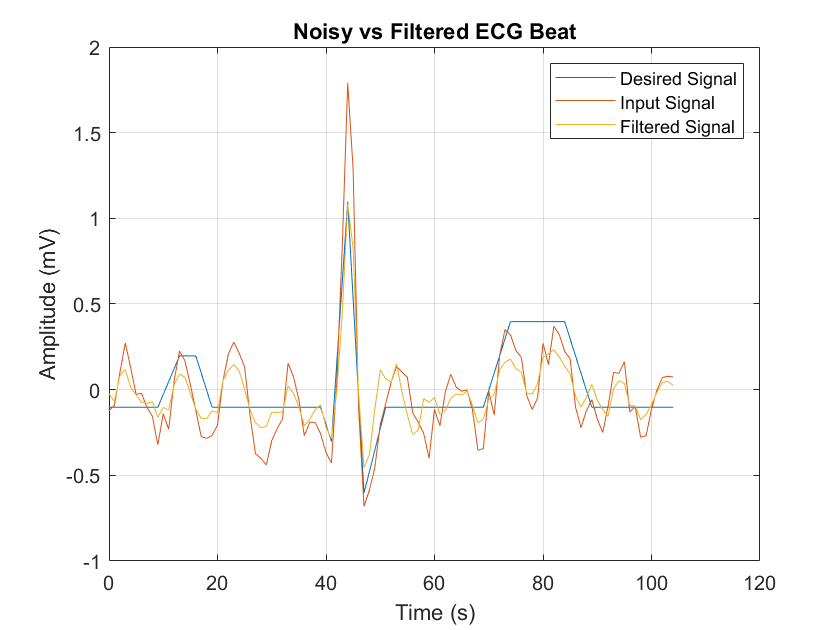

M = 20; %Filter order

% Autocorrelation of desired
R_YY = xcorr(y_seg_2, M-1, 'unbiased');
R_YY_M = toeplitz(R_YY(M:end));

% Autocorrelation of noise
R_NN = xcorr(n_seg1, M-1, 'unbiased');
R_NN_M = toeplitz(R_NN(M:end));

% Cross-correlation vector (between y and itself at zero lag)
R_Yy = R_YY(M:end);

% Wiener solution
w = (R_YY_M + R_NN_M)\ R_Yy(:);
y_hat = filter(w, 1, x_in); % Apply filter
x_seg = x_in(s1:e1);
y_hat_seg = y_hat(s1:e1);

% Local time axis for 105 samples
t_seg = (0:length(y_seg_2)-1)/fs;

figure;
plot(t, y_seg_2, t, x_seg, t, y_hat_seg); 

legend('Desired Signal','Input Signal','Filtered Signal');
xlabel('Time (s)'); ylabel('Amplitude (mV)');
title('Noisy vs Filtered ECG Beat');
grid on;



%% (b) Wiener filter design, sweep orders
M_range = 1:30;
MSE_matrix = zeros(size(M_range));
w_bank = cell(size(M_range));

for k = 1:length(M_range)
    M = M_range(k);

    % Autocorr matrices
    Ryy = xcorr(y_seg_2, M-1, 'unbiased');
    RyyM = toeplitz(Ryy(M:end));

    Rnn = xcorr(n_seg1, M-1, 'unbiased');
    RnnM = toeplitz(Rnn(M:end));

    % Cross-corr vector (assignment style)
    Ryy_cross = Ryy(M:end);

    % Wiener solution
    w_k = (RyyM + RnnM) \ Ryy_cross(:);
    w_bank{k} = w_k;

    % Filter noisy input
    y_hat_k = filter(w_k, 1, x_in);

    % Extract the beat region
    y_hat_seg = y_hat_k(s1:e1);
    
    % Compute MSE on same length
    MSE_matrix(k) = mean((y_seg_2 - y_hat_seg).^2);
   
end

% Find optimum order
[minMSE, idx] = min(MSE_matrix);
M_opt = M_range(idx);
w_optimal = w_bank{idx};

fprintf('Optimum filter order (Part 2) = %d, Minimum MSE = %.6f\n', M_opt, minMSE)

Optimum filter order (Part 2) = 19, Minimum MSE = 0.023813


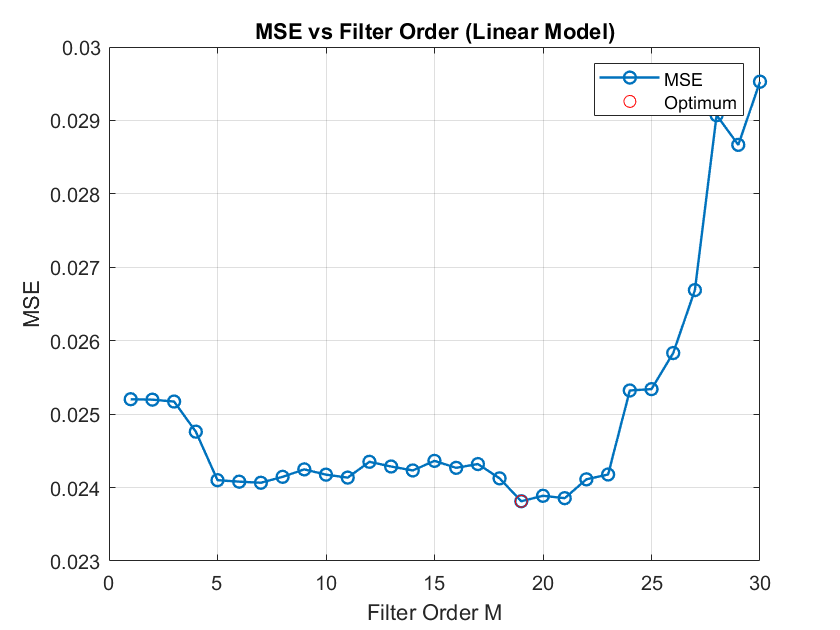


% Plot MSE vs order
figure; plot(M_range, MSE_matrix,'-o','LineWidth',1.2); grid on;
xlabel('Filter Order M'); ylabel('MSE');
title('MSE vs Filter Order (Linear Model)');
hold on; plot(M_opt, minMSE,'ro'); legend('MSE','Optimum');

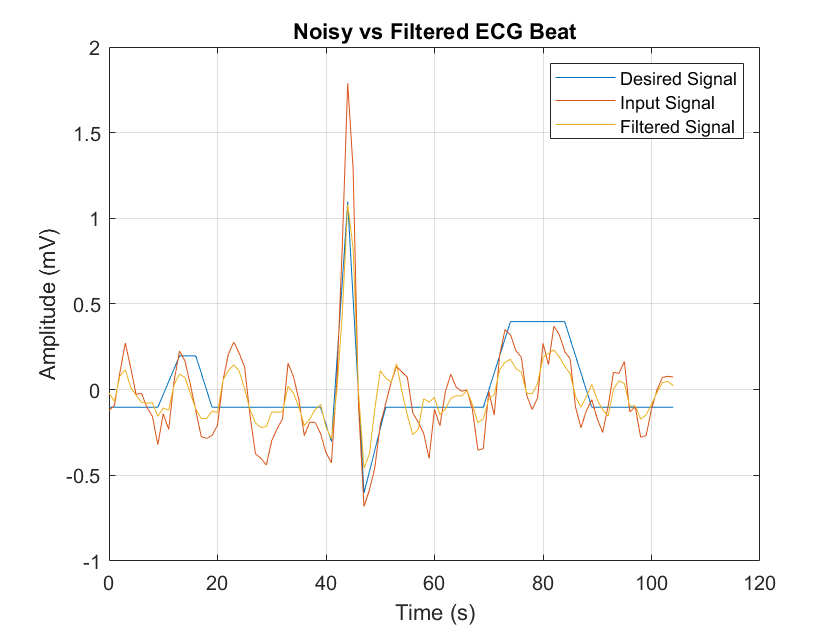


%% --- (c) Filter with optimum filter
y_hat_opt = filter(w_optimal, 1, x_in);
y_hat_opt = y_hat_opt(s1:e1);

figure;
plot(t, y_seg_2, t, x_seg, t,y_hat_opt); 

legend('Desired Signal','Input Signal','Filtered Signal');
xlabel('Time (s)'); ylabel('Amplitude (mV)');
title('Noisy vs Filtered ECG Beat');
grid on;

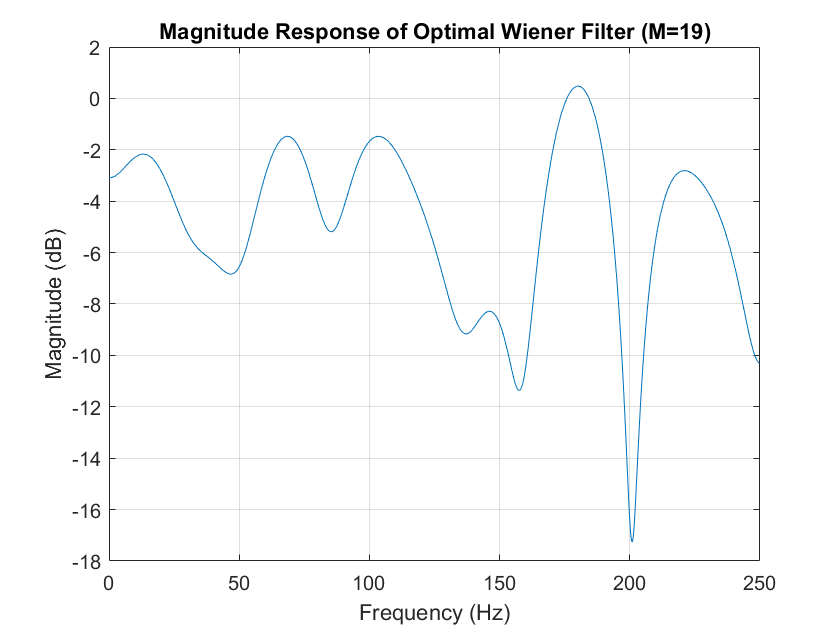

% Magnitude response
[H, f] = freqz(w_optimal, 1, 1024, fs);
figure;
plot(f, 20*log10(abs(H)+eps));
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
title(sprintf('Magnitude Response of Optimal Wiener Filter (M=%d)', M_opt));
grid on;

% (d) Plot the spectra of 𝑦𝑖(𝑛), 𝜂(𝑛), 𝑥(𝑛), 𝑦̂(𝑛) on the same plot
N = length(y_ideal);
window = rectwin(N);


[P1,f1] = periodogram(y_ideal, window, N, fs);   % PSD estimate of a of 𝑦𝑖(𝑛)
[P2,f2] = periodogram(noise, window, N, fs);   % PSD estimate of 𝜂(𝑛)
[P3,f3] = periodogram(x, window, N, fs);    % PSD estimate of 𝑥(𝑛)
[P4,f4] = periodogram(y_optimal, window, N, fs);    % PSD estimate of 𝑦̂(𝑛)

figure();
plot(f1, 10*log10(P1), f2, 10*log10(P2), f3, 10*log10(P3), f4, 10*log10(P4));   % Plotting the PSDs
title('PSD estimate of 𝑦𝑖(𝑛), 𝜂(𝑛), 𝑥(𝑛), 𝑦̂(𝑛)');
xlabel('Frequency (Hz)');
ylabel('Power/frequency (dB/Hz)');
legend('𝑦𝑖(𝑛)', '𝜂(𝑛)', '𝑥(𝑛)', '𝑦̂(𝑛)');
grid on;

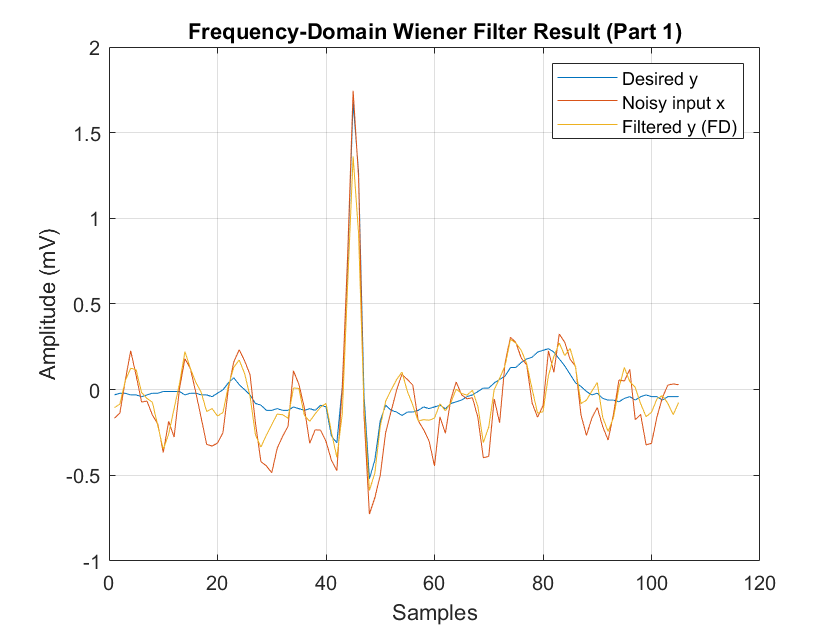

%% 1.2 Frequency Domain Wiener Filter Implementation 
% Part 1

len_x = length(x);

% Compute PSDs using FFT
S_yy = abs(fft(y_seg, 2*len_x-1)).^2;   % PSD of desired
S_nn = abs(fft(n_seg1, 2*len_x-1)).^2;  % PSD of noise

% Wiener filter in frequency domain
W_f = S_yy ./ (S_yy + S_nn + eps);

% Apply filter
S_xx = fft(x, 2*len_x-1);
S_hat_yy = W_f .* S_xx;

% Inverse FFT to reconstruct filtered signal
yhat_f = ifft(S_hat_yy);
yhat_f = real(yhat_f(1:len_x));

%% --- Compare signals ---
figure;
plot(y_seg); hold on;
plot(x(s1:e1));
plot(yhat_f(s1:e1));
legend('Desired y','Noisy input x','Filtered y (FD)');
xlabel('Samples'); ylabel('Amplitude (mV)');
title('Frequency-Domain Wiener Filter Result (Part 1)');
grid on;


%% --- MSE ---
MSE_fd = mean((y_seg - yhat_f(s1:e1)).^2);
fprintf('Frequency-domain Wiener filter MSE = %.6f\n', MSE_fd);

Frequency-domain Wiener filter MSE = 0.017335


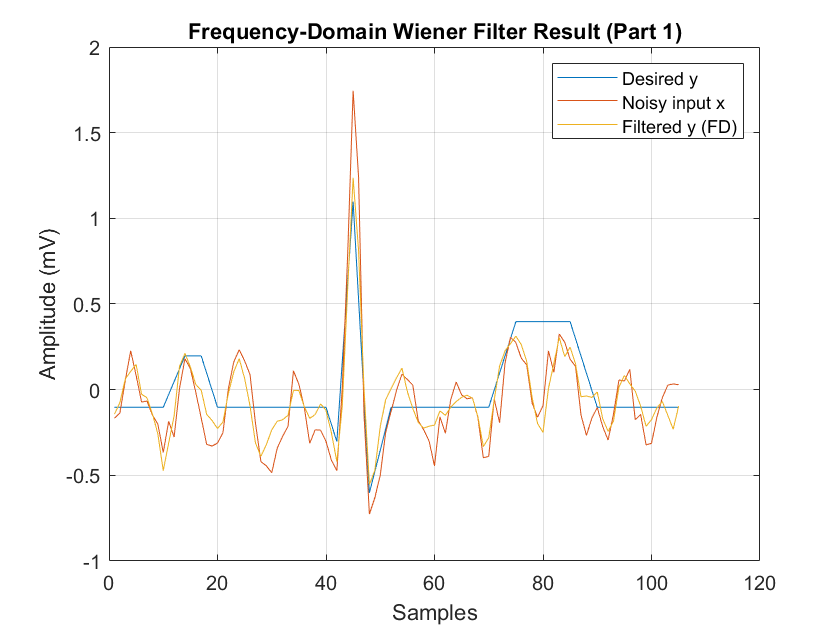

%% 1.2 Frequency Domain Wiener Filter Implementation 
% Part2

len_x = length(x);

% Compute PSDs using FFT
S_yy = abs(fft(y_seg_2, 2*len_x-1)).^2;   % PSD of desired
S_nn = abs(fft(n_seg1, 2*len_x-1)).^2;  % PSD of noise

% Wiener filter in frequency domain
W_f = S_yy ./ (S_yy + S_nn + eps);

% Apply filter
S_xx = fft(x, 2*len_x-1);
S_hat_yy = W_f .* S_xx;

% Inverse FFT to reconstruct filtered signal
yhat_f = ifft(S_hat_yy);
yhat_f = real(yhat_f(1:len_x));

%% --- Compare signals ---
figure;
plot(y_seg_2); hold on;
plot(x(s1:e1));
plot(yhat_f(s1:e1));
legend('Desired y','Noisy input x','Filtered y (FD)');
xlabel('Samples'); ylabel('Amplitude (mV)');
title('Frequency-Domain Wiener Filter Result (Part 1)');
grid on;


%% --- MSE ---
MSE_fd = mean((y_seg - yhat_f(s1:e1)).^2);
fprintf('Frequency-domain Wiener filter MSE = %.6f\n', MSE_fd);

Frequency-domain Wiener filter MSE = 0.025924


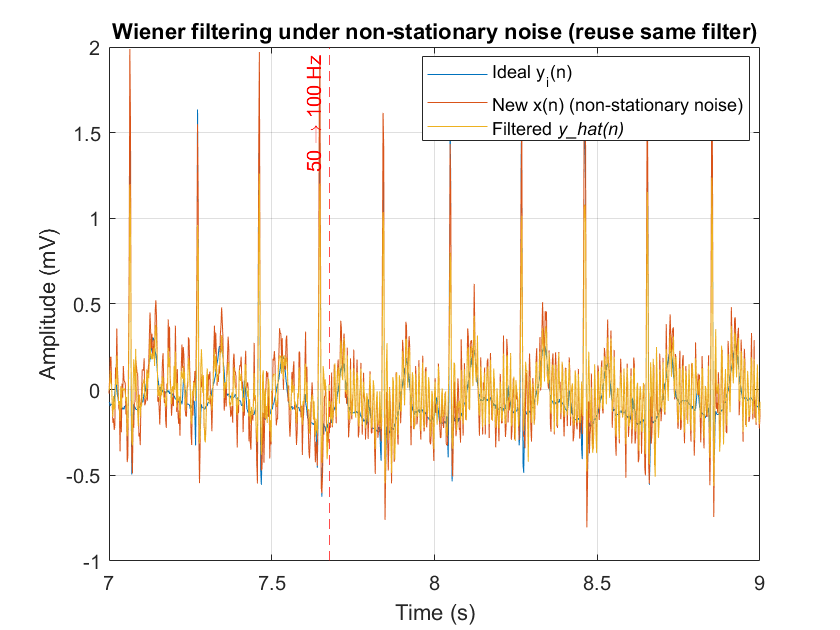


% 1.3 Effect on non-stationary noise on Wiener filtering
%% 1.3 Non-stationary noise: 50 Hz first half, 100 Hz second half
N  = length(y_ideal);
t  = (0:N-1)/fs;

% White noise with ~10 dB SNR w.r.t. y_ideal (matches your Part 1 setting)
sigma = std(y_ideal) / (10^(10/20));     % 10 dB SNR
eta_wg = sigma * randn(1, N);

% Sinusoids
eta50  = 0.2 * sin(2*pi*50 * t);
eta100 = 0.2 * sin(2*pi*100 * t);

% Build the non-stationary noise: 50 Hz then 100 Hz
halfN = floor(N/2);
eta_ns = eta_wg;
eta_ns(1:halfN)        = eta_wg(1:halfN)        + eta50(1:halfN);
eta_ns(halfN+1:end)    = eta_wg(halfN+1:end)    + eta100(halfN+1:end);

% New observation x_ns(n) and offset correction
x_ns  = y_ideal(:).' + eta_ns;
x_ns  = x_ns - mean(x_ns);

%% (a) Apply ONE of your previously-derived Wiener filters (do NOT recalc)

if exist('w_optimal','var')
    % --- Time-domain Wiener FIR from §1.1 ---
    yhat_ns = filter(w_optimal, 1, x_ns);
elseif exist('W_f','var')
    % --- Frequency-domain Wiener from §1.2 ---
    Nfft = length(W_f);                    % reuse same FFT length you used before
    Xf   = fft(x_ns, Nfft);
    Yf   = W_f .* Xf;                      % apply same W(f) as before
    yhat_tmp = real(ifft(Yf, Nfft));
    yhat_ns  = yhat_tmp(1:N);              % crop to time length
else
    error('No existing Wiener filter found. Define w_optimal (time-domain) or W_f (frequency-domain) first.');
end

%% (b) Plot time-domain result and annotate halves
figure; 
plot(t, y_ideal); hold on;
plot(t, x_ns); 
plot(t, yhat_ns);
xline(t(halfN), '--r', '50 \rightarrow 100 Hz', 'LabelHorizontalAlignment','left');
xlim([7 9] )
legend('Ideal y_i(n)','New x(n) (non-stationary noise)','Filtered \ity\_hat(n)','Location','best');
xlabel('Time (s)'); ylabel('Amplitude (mV)');
title('Wiener filtering under non-stationary noise (reuse same filter)');
grid on;


% MSE (vs ideal) 
MSE_all   = mean( (y_ideal(:).' - yhat_ns).^2 );
MSE_1st   = mean( (y_ideal(1:halfN)   - yhat_ns(1:halfN)).^2 );
MSE_2nd   = mean( (y_ideal(halfN+1:end)- yhat_ns(halfN+1:end)).^2 );
fprintf('MSE(all)=%.6f | MSE(0–T/2, 50 Hz)=%.6f | MSE(T/2–T, 100 Hz)=%.6f\n', MSE_all, MSE_1st, MSE_2nd);

MSE(all)=0.024959 | MSE(0–T/2, 50 Hz)=0.020201 | MSE(T/2–T, 100 Hz)=0.029716



%2. Adaptive filtering



% 2.1 LMS method

clear; clc;

phi = pi/6; % Phase shift
snr = 15;   % SNR in dB units

N = 5000;   % Number of samples
t = linspace(0, 5, N)'; % Time vector with fs = 500 Hz
s = sawtooth(2 * pi * 2 * t(1:N,1), 0.5);  % Sawtooth signal of 0.5 width
n1 = 0.2 * sin(2 * pi * 50 * t(1:N/2,1) - phi);   % Sinusoid at 50Hz
n2 = 0.3 * sin(2 * pi * 100 * t(N/2+1:N,1) - phi);    % Sinusoid at 100Hz
nwg = s - awgn(s, snr, 'measured');   % Gaussian white noise

non_stationary_noise = [n1; n2];    % Concatenate n1 and n2 noise 
noise = non_stationary_noise + nwg;

x_in = noise + s;   % Input signal
r_n = 0.6* (nwg + sin(2*pi*50*t + pi/4) + sin(2*pi*100*t + pi/6));

% Save the x_in and r_n vectors to a .mat file
save('r_n', 'r_n'); save('x_in', 'x_in');

% (a) Implement the LMS method

order_lms = 21; % LMS filter order
step_lms = 0.01;    % Step size 
[~, ~, e_lms] = LMS_Filter(r_n, x_in, step_lms, order_lms);

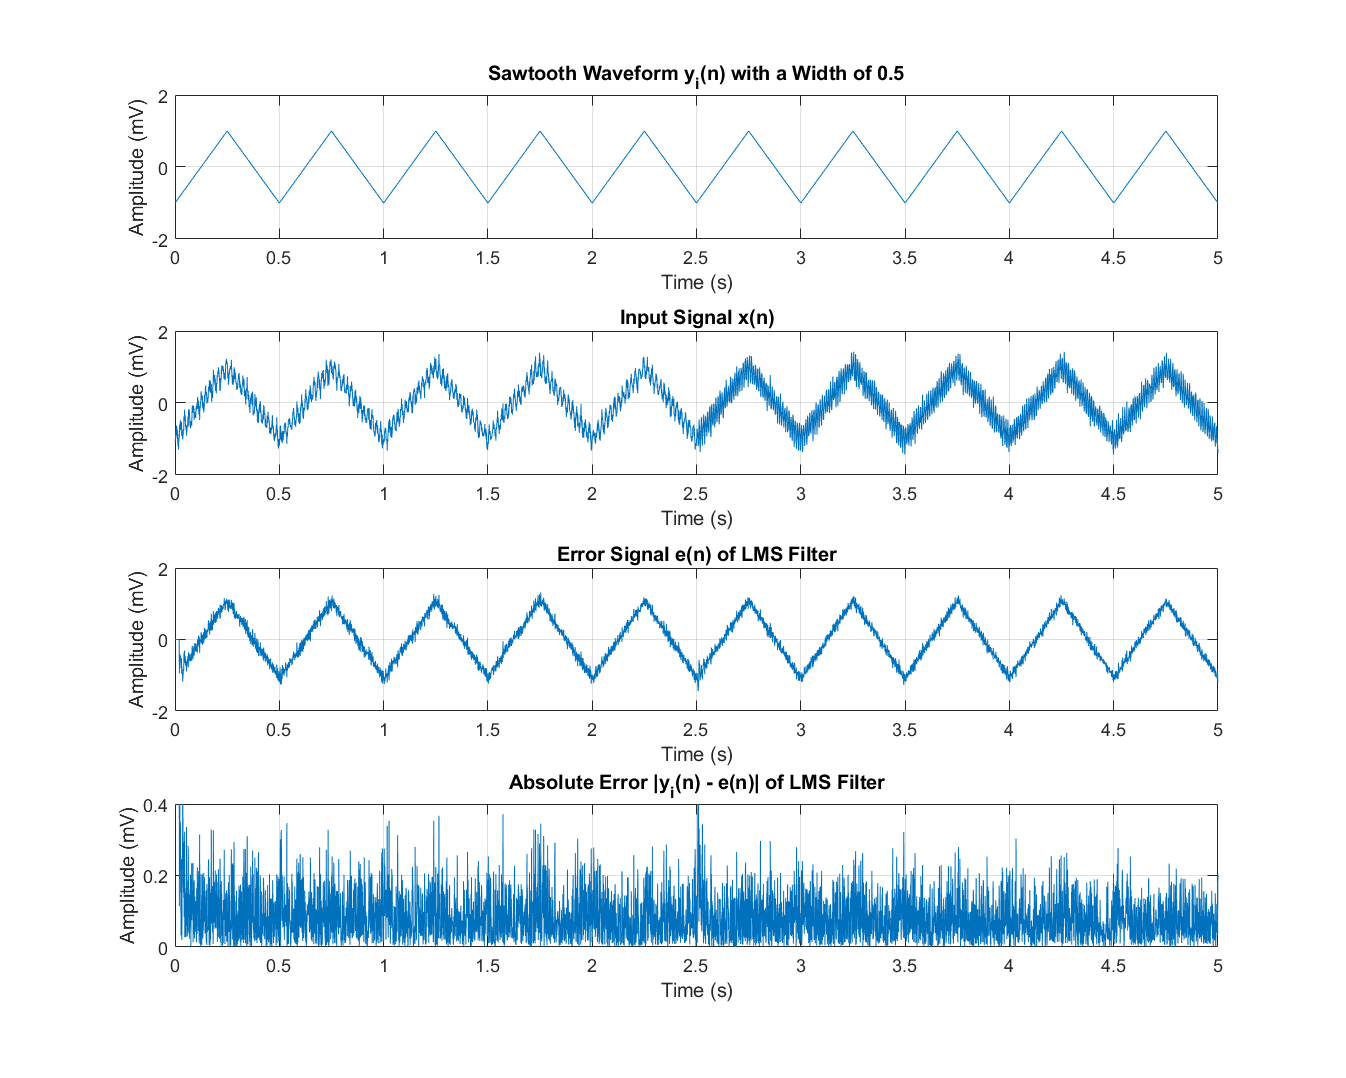

% (b) Plot the signals 𝑦𝑖(𝑛), 𝑥(𝑛), 𝑒(𝑛) = 𝑦̂(𝑛) and the absolute error |𝑦𝑖(𝑛) − 𝑦̂(𝑛)|

% Plot the signal yi(n)
figure('Position', [100, 100, 1000, 800]);   % Set figure size
subplot(4, 1, 1);
plot(t, s);
title('Sawtooth Waveform y_{i}(n) with a Width of 0.5');
ylim([-2, 2]);
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;

% Plot the input signal x(n)
subplot(4, 1, 2);
plot(t, x_in);
title('Input Signal x(n)');
ylim([-2, 2]);
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;

% Plot the error signal e(n)
subplot(4, 1, 3);
plot(t, e_lms);
title('Error Signal e(n) of LMS Filter');
ylim([-2, 2]);
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;

% Plot the absolute error signal |yi(n) - e(n)|
subplot(4, 1, 4);
plot(t, abs(s - e_lms));
title('Absolute Error |y_{i}(n) - e(n)| of LMS Filter');
ylim([0, 0.4]);
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;

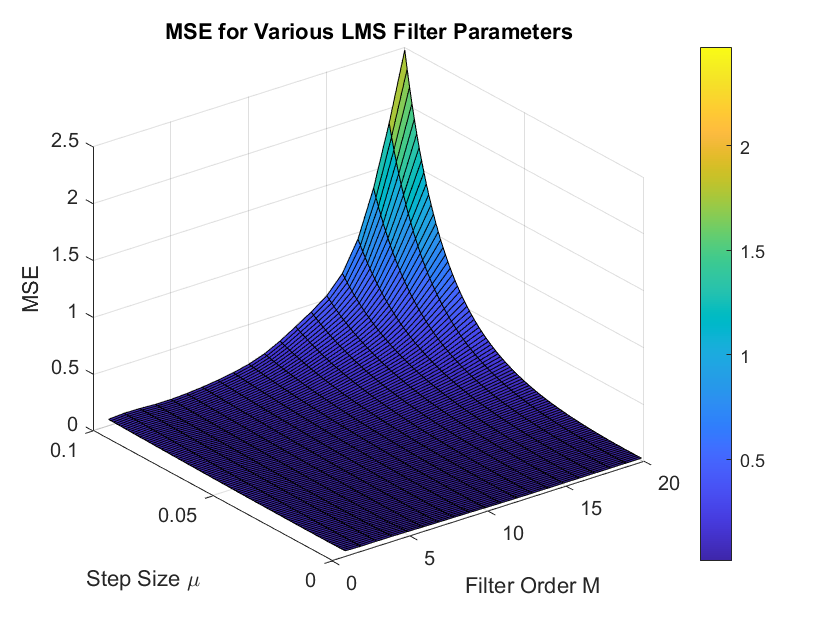

% (c) Explore the rate of adaptation by varying the rate of convergence 𝜇 and the order of the adaptive filter (𝑀 − 1)

% Define the range of order and step to test
order_range = 1:1:20; % Different filter orders
step_range = 0.001:0.001:0.1;  % Step sizes from 0.001 to 0.1

% Initialize the matrix to store MSE values
MSE_matrix = zeros(length(step_range), length(order_range));

% Loop over all combinations of N and L
for i = 1 : length(order_range)
    for j = 1 : length(step_range)
        [~, ~, e_lms] = LMS_Filter(r_n, x_in, step_range(j), order_range(i));
        MSE_matrix(j, i) = mean((s - e_lms).^2);
    end
end

% Plot the MSE matrix
figure();
surf(order_range, step_range, MSE_matrix);
xlabel('Filter Order M');
ylabel('Step Size \mu');
zlabel('MSE');
title('MSE for Various LMS Filter Parameters');
colorbar;
grid on;

% Find the minimum MSE and corresponding indices
[minMSE, idx] = min(MSE_matrix(:));
[j, i] = ind2sub(size(MSE_matrix), idx);
optOrder_lms = order_range(i);
optStep = step_range(j);
fprintf('The optimum filter parameters which gives the minimum MSE are for M = %d and \x03BC = %f. It gives an MSE value of %f', optOrder_lms, optStep, minMSE);

The optimum filter parameters which gives the minimum MSE are for M = 12 and μ = 0.009000. It gives an MSE value of 0.012239

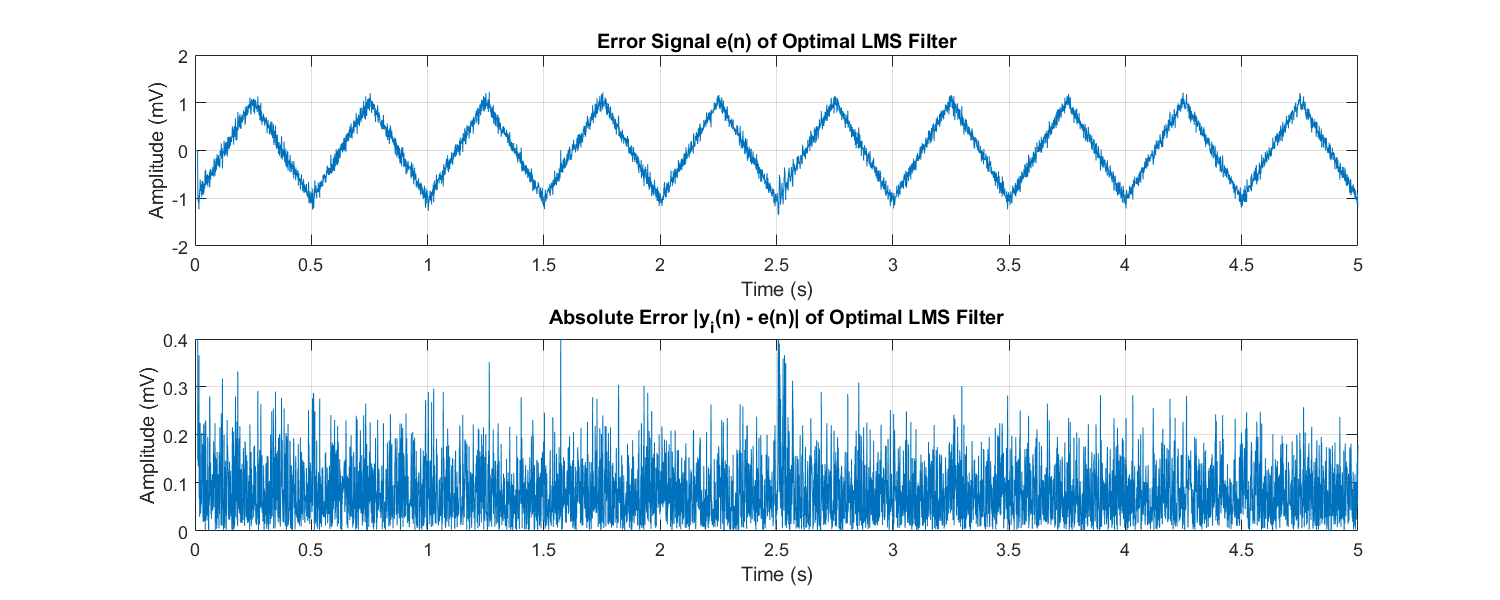

[~, ~, e_lms] = LMS_Filter(r_n, x_in, optStep, optOrder_lms);

% Plot the error signal e(n)
figure('Position', [100, 100, 1000, 400]);
subplot(2, 1, 1);
plot(t, e_lms);
title('Error Signal e(n) of Optimal LMS Filter');
ylim([-2, 2]);
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;

% Plot the absolute error signal |yi(n) - e(n)|
subplot(2, 1, 2);
plot(t, abs(s - e_lms));
title('Absolute Error |y_{i}(n) - e(n)| of Optimal LMS Filter');
ylim([0, 0.4]);
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;

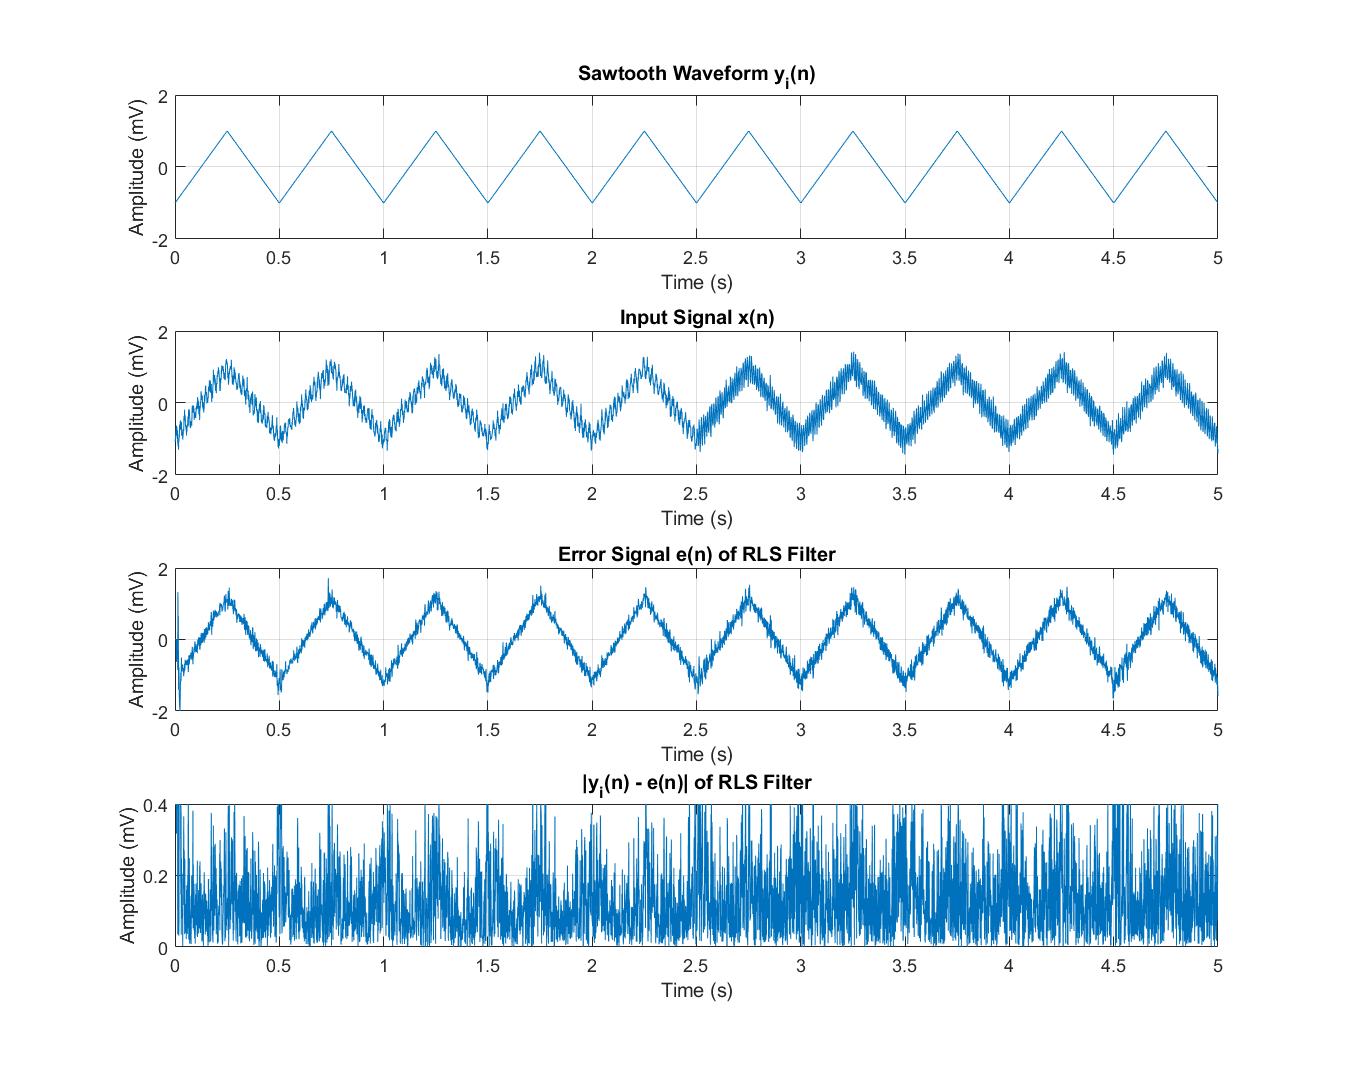

% 2.1 RLS method

% (a) Implement the RLS method
order_rls = 7;   % RLS filter order
lambda    = 0.95; % Forgetting factor

load('r_n'); load('x_in');

[~, ~, e_rls] = RLS_Filter(r_n, x_in, lambda, order_rls);

% (b) Compare the performance of LMS and RLS algorithms using a plot
figure('Position', [100, 100, 1000, 800]);
subplot(4,1,1);
plot(t, s); title('Sawtooth Waveform y_{i}(n)'); ylim([-2,2]);
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;

subplot(4,1,2);
plot(t, x_in); title('Input Signal x(n)'); ylim([-2,2]);
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;

subplot(4,1,3);
plot(t, e_rls); title('Error Signal e(n) of RLS Filter'); ylim([-2,2]);
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;

subplot(4,1,4);
plot(t, abs(s - e_rls));
title('|y_{i}(n) - e(n)| of RLS Filter'); ylim([0,0.4]);
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;

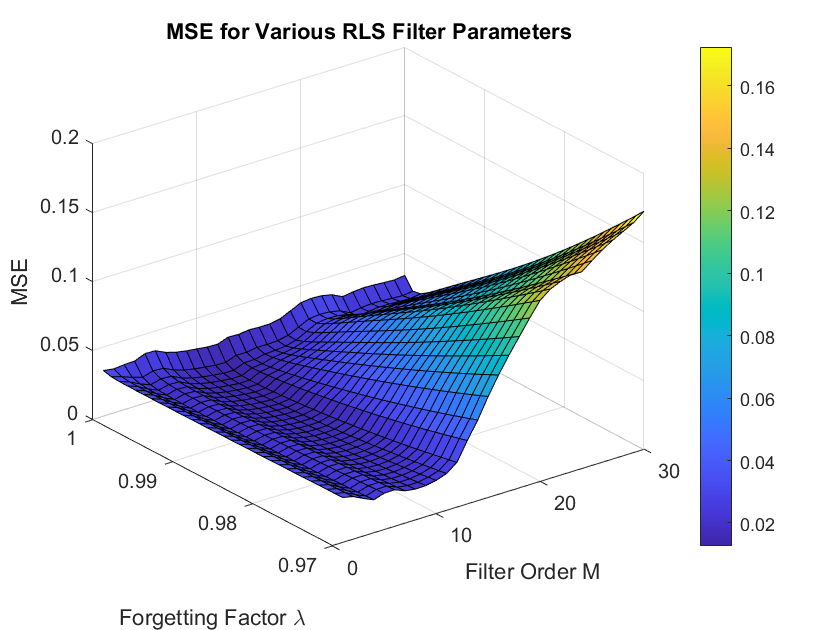


% (c) Explore λ and M for adaptation
order_range  = 1:1:30;
lambda_range = 0.97:0.001:1;
MSE_matrix   = zeros(length(lambda_range), length(order_range));

for i = 1:length(order_range)
    for j = 1:length(lambda_range)
        [~, ~, e_rls] = RLS_Filter(r_n, x_in, lambda_range(j), order_range(i));
        MSE_matrix(j,i) = mean((s - e_rls).^2);
    end
end

figure();
surf(order_range, lambda_range, MSE_matrix);
xlabel('Filter Order M'); ylabel('Forgetting Factor \lambda'); zlabel('MSE');
title('MSE for Various RLS Filter Parameters'); colorbar; grid on;


[minMSE, idx] = min(MSE_matrix(:));
[j,i] = ind2sub(size(MSE_matrix), idx);
optOrder_rls = order_range(i);
optLambda    = lambda_range(j);
fprintf('Optimum RLS: M = %d, λ = %.3f, MSE = %.6f\n', ...
    optOrder_rls, optLambda, minMSE);

Optimum RLS: M = 11, λ = 0.995, MSE = 0.012631


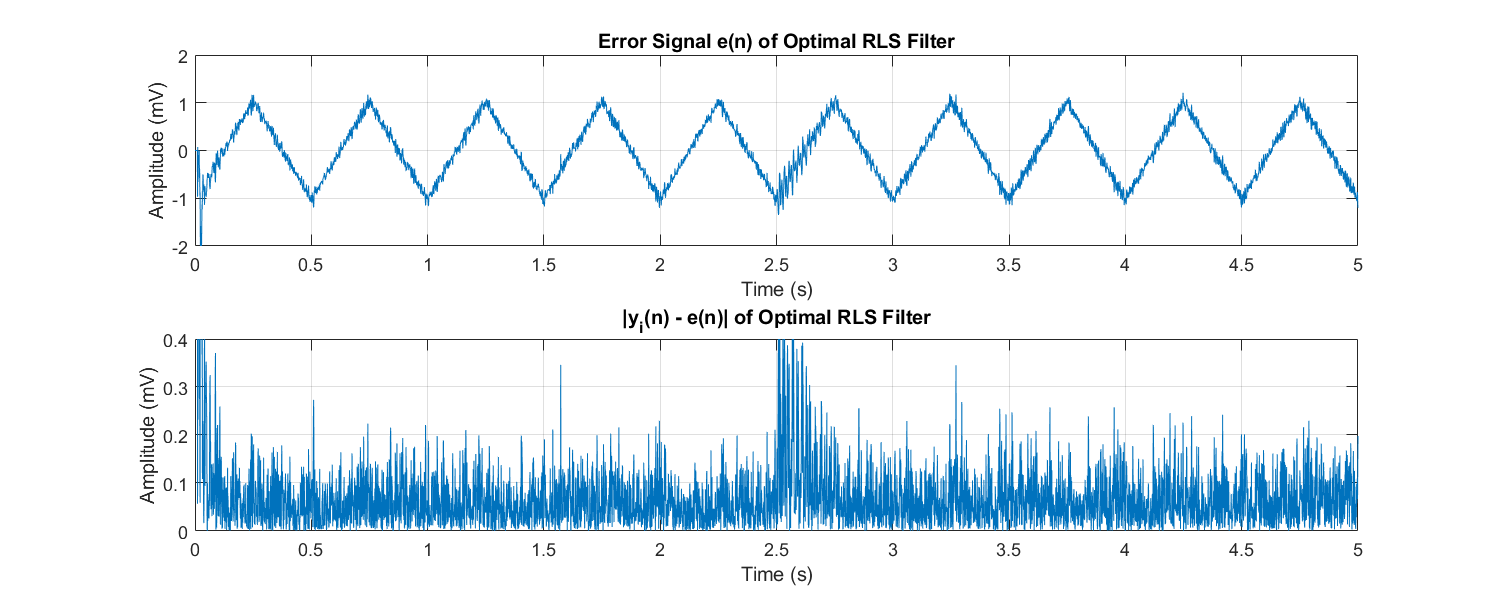


[~, ~, e_rls] = RLS_Filter(r_n, x_in, optLambda, optOrder_rls);

figure('Position', [100,100,1000,400]);
subplot(2,1,1);
plot(t, e_rls); title('Error Signal e(n) of Optimal RLS Filter');
ylim([-2,2]); xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;

subplot(2,1,2);
plot(t, abs(s - e_rls));
title('|y_{i}(n) - e(n)| of Optimal RLS Filter'); ylim([0,0.4]);
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;

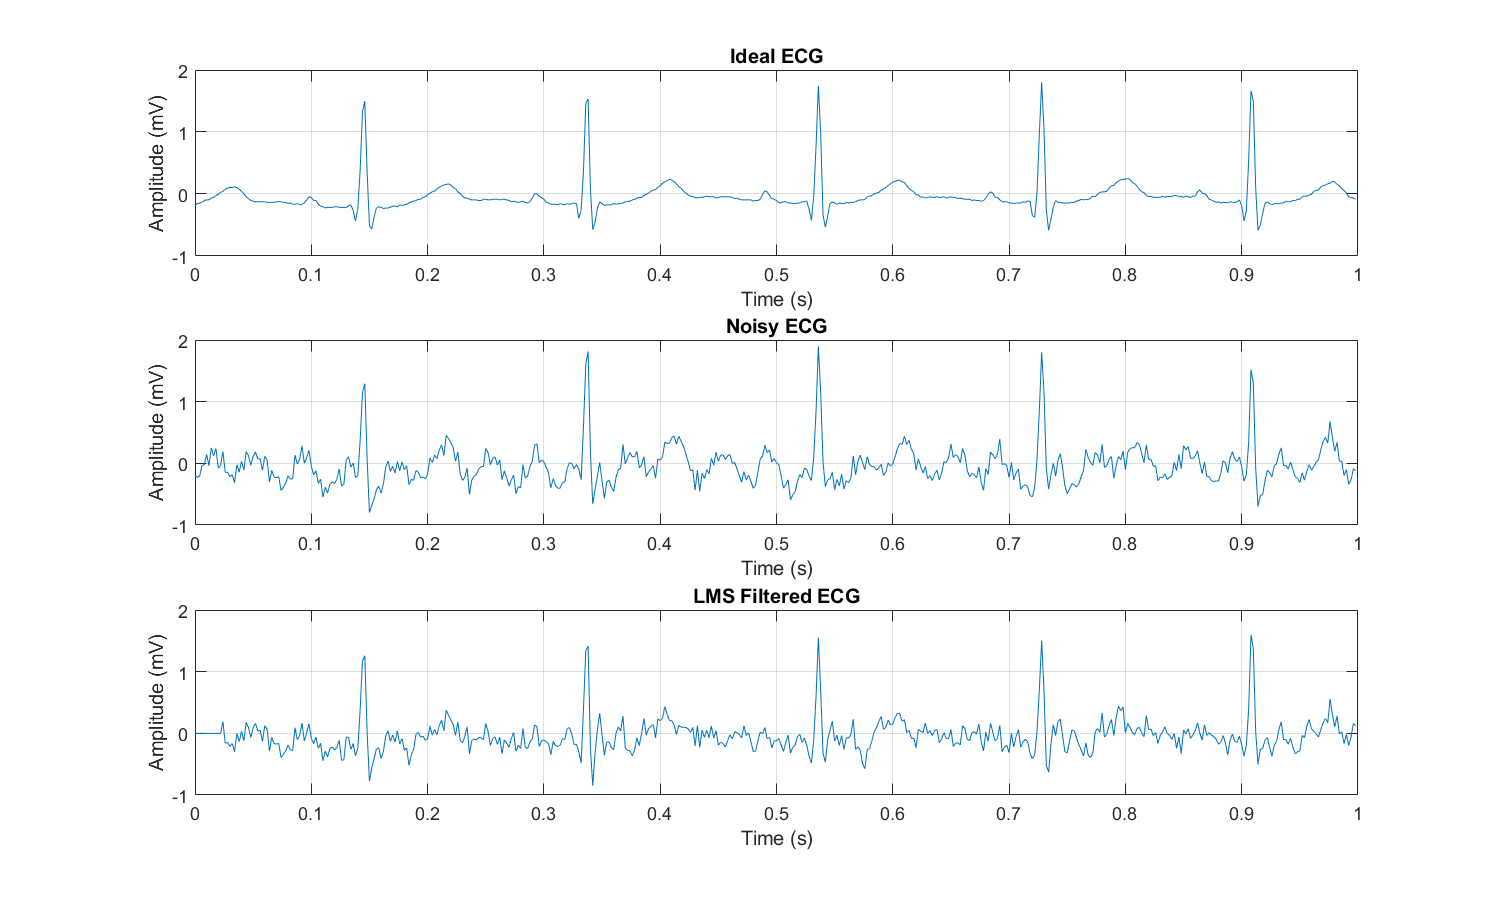


% (d) Test LMS and RLS on idealECG
load('idealECG.mat');
idealECG = idealECG(1:5000);
fs = 500;
t_ecg = (0:N-1)'/fs;
x_in = idealECG' + noise;

[~, ~, ECG_LMS] = LMS_Filter(r_n, x_in, optStep, optOrder_lms);
[~, ~, ECG_RLS] = RLS_Filter(r_n, x_in, optLambda, optOrder_rls);

figure('Position',[100,100,1000,600]);
subplot(3,1,1); plot(t_ecg(1:500), idealECG(1:500)); title('Ideal ECG');
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;
subplot(3,1,2); plot(t_ecg(1:500), x_in(1:500)); title('Noisy ECG');
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;
subplot(3,1,3); plot(t_ecg(1:500), ECG_LMS(1:500)); title('LMS Filtered ECG');
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;

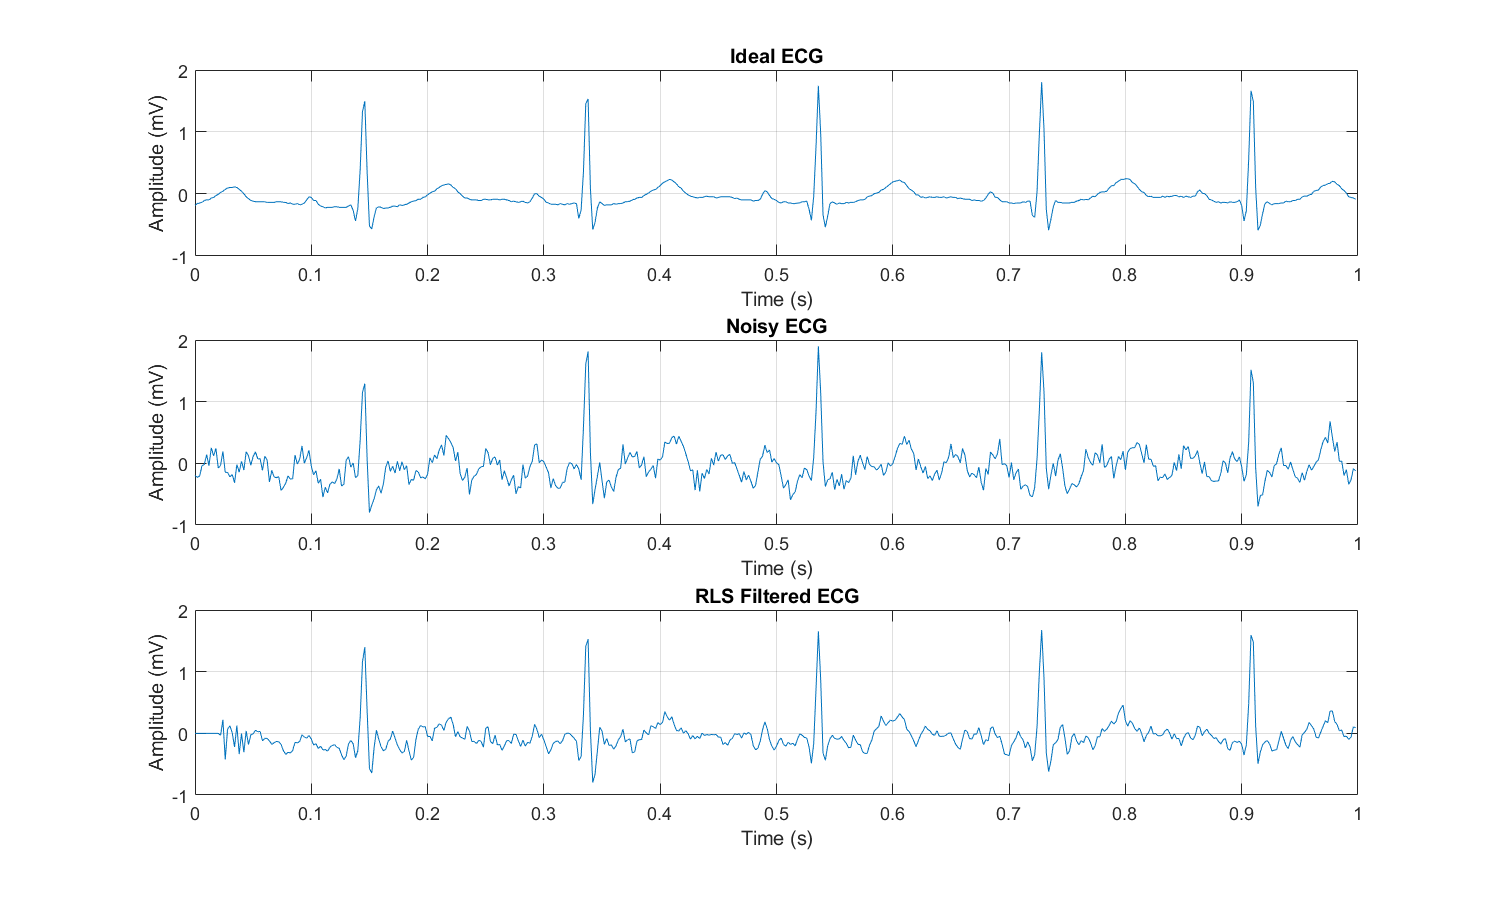


figure('Position',[100,100,1000,600]);
subplot(3,1,1); plot(t_ecg(1:500), idealECG(1:500)); title('Ideal ECG');
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;
subplot(3,1,2); plot(t_ecg(1:500), x_in(1:500)); title('Noisy ECG');
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;
subplot(3,1,3); plot(t_ecg(1:500), ECG_RLS(1:500)); title('RLS Filtered ECG');
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;


%% --- Local function inside script ---

function [w,y,e] = RLS_Filter(r_n, x_n, lambda, M)
    K = M + 1; N = length(x_n);
    P = 1e3*eye(K);       % large value for inverse correlation matrix
    w = zeros(K,1);       
    y = zeros(N,1);       
    e = zeros(N,1);       

    for n = K:N
        r = r_n(n:-1:n-K+1);             % input vector
        k = (P*r) / (lambda + r'*P*r);   % Kalman gain vector
        e(n) = x_n(n) - w'*r;            % a priori error
        w = w + k*e(n);                  % weight update
        P = (P - k*r'*P)/lambda;         % matrix inverse update
        y(n) = w'*r;                     % filter output (noise est.)
    end
end



%% --- Local LMS function inside script ---
function [w, y, e] = LMS_Filter(r_n, x_n, mu, M)
    K = M + 1;              % number of filter coefficients
    N = length(x_n);
    w = zeros(K,1);         % weight vector
    y = zeros(N,1);         % output
    e = zeros(N,1);         % error
    for n = K:N
        r = r_n(n:-1:n-K+1);    % input vector
        y(n) = w' * r;          % filter output
        e(n) = x_n(n) - y(n);   % error
        w = w + 2*mu*e(n)*r;    % weight update
    end
end

